# MPC tuning with Bayesian Optimization

clc
clf
clear all
close all
rng(0)

## Parallel computing

if isempty(gcp('nocreate'))
    cluster = parcluster('local');
    parpool(cluster, cluster.NumWorkers);
end
p = gcp();
fprintf('Using %d parallel workers', p.NumWorkers);

Using 8 parallel workers

## Define optimization variables

% lambda_z = optimizableVariable('lambda_z', [1e-4, 1e-2], 'Transform', 'log');
% lambda_o = optimizableVariable('lambda_o', [1e-3, 1e-1], 'Transform', 'log');
% lambda   = optimizableVariable('lambda'  , [1e-2, 1], 'Transform', 'log');

% lambda_z = optimizableVariable('lambda_z', [1e-5, 1e-1], 'Transform', 'log');
% lambda_o = optimizableVariable('lambda_o', [1e-5, 1e-1], 'Transform', 'log');
% lambda   = optimizableVariable('lambda'  , [1e-5, 1e-1], 'Transform', 'log');

lambda_z = optimizableVariable('lambda_z', [1e-7, 1e-1], 'Transform', 'log');
lambda_o = optimizableVariable('lambda_o', [1e-7, 1e-1], 'Transform', 'log');
lambda   = optimizableVariable('lambda'  , [1e-7, 1e-1], 'Transform', 'log');

optimization_variables = [lambda_z, lambda_o, lambda];
nVars = size(optimization_variables, 2);

## Objective function

Simulate MMCC + Induction Machine and calculate MPC mean cost

function cost = objective_function(x)
    try
        cost = simulate(x);
    catch
        cost = 10;
    end
end

## Bayesian optimization

Copying objective function to workers...
Done copying objective function to workers.
|==============================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |     lambda_z |     lambda_o |       lambda |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|==============================================================================================================================|
|    1 |       8 | Best   |     0.18801 |       62.65 |     0.18801 |     0.18801 |    0.0036419 |     0.018204 |   1.9602e-05 |
|    2 |       2 | Accept |     0.23291 |      63.515 |     0.18522 |     0.18522 |    0.0021021 |   0.00010648 |   0.00014524 |
|    3 |       2 | Best   |     0.18522 |      65.739 |     0.18522 |     0.18522 |   2.6977e-05 |    0.0072979 |    4.015e-05 |
|    4 |    

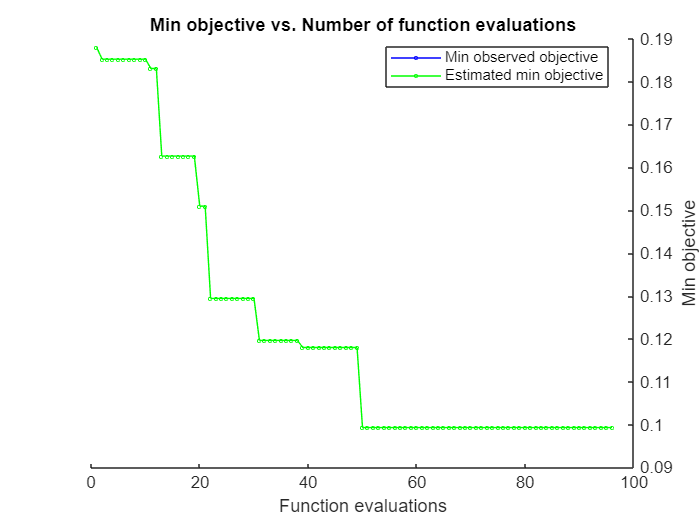

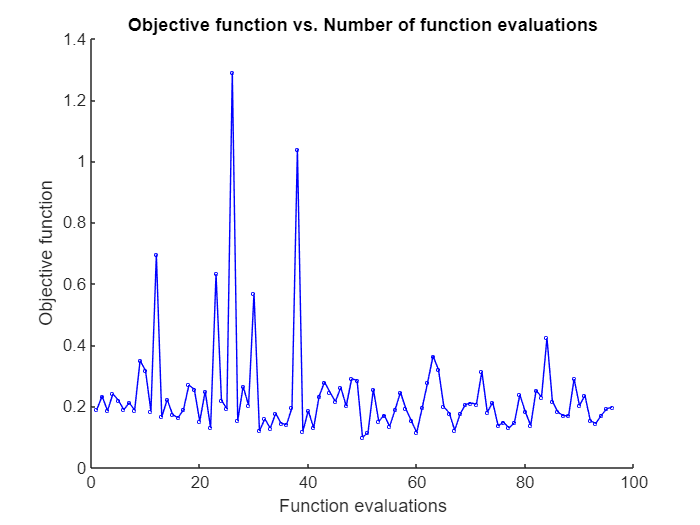

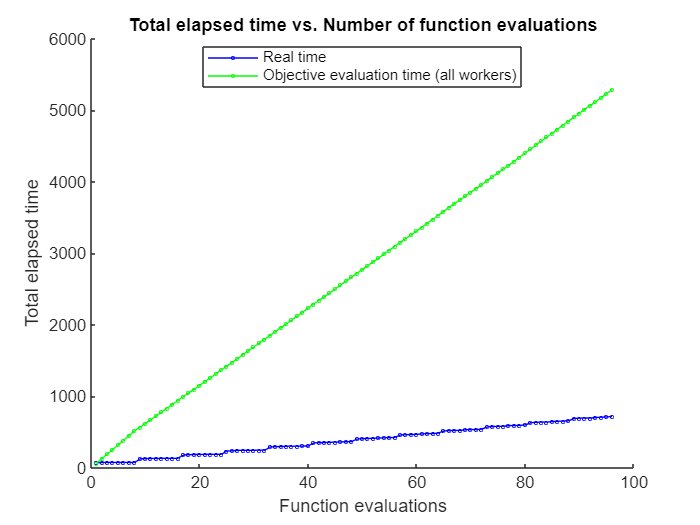

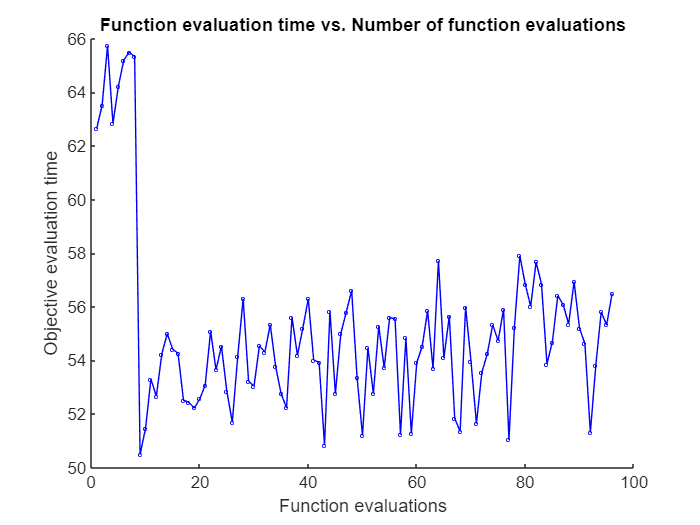

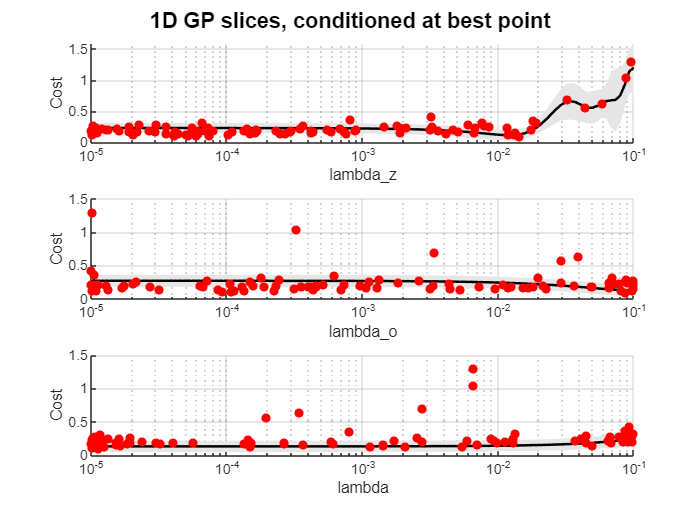

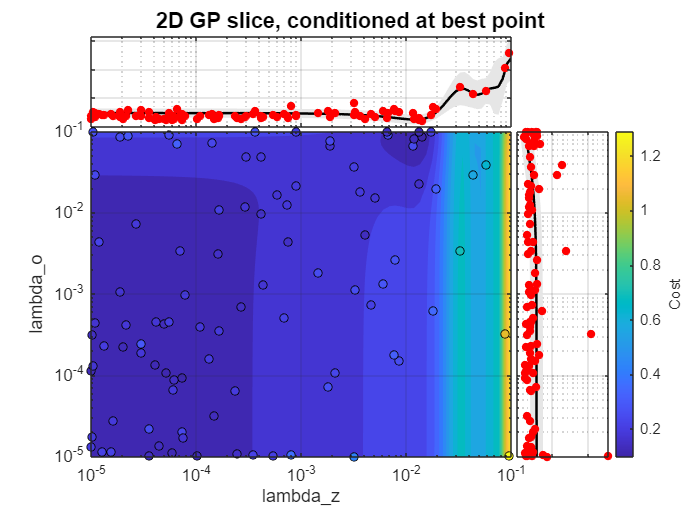


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 96 reached.
Total function evaluations: 96
Total elapsed time: 713.0671 seconds
Total objective function evaluation time: 5287.6431

Best observed feasible point:
    lambda_z    lambda_o      lambda  
    ________    ________    __________
    0.014383    0.086682    1.1265e-05
Observed objective function value = 0.09931
Estimated objective function value = 0.09931
Function evaluation time = 51.1938

Best estimated feasible point (according to models):
    lambda_z    lambda_o      lambda  
    ________    ________    __________
    0.014383    0.086682    1.1265e-05
Estimated objective function value = 0.09931
Estimated function evaluation time = 52.9995



NumSeedPoints = 10*p.NumWorkers;
lb = log10([1e-7, 1e-7, 1e-7]);
ub = log10([1e-1, 1e-1, 1e-1]);

Xlhs = lhsdesign(NumSeedPoints, nVars);
Xinit = 10 .^ bsxfun(@plus, lb, bsxfun(@times, (ub-lb), Xlhs));
Xinit = array2table(Xinit, 'VariableNames', {'lambda_z','lambda_o','lambda'});

results = bayesopt(@objective_function, optimization_variables, ...
    'MaxObjectiveEvaluations',   100*p.NumWorkers, ...
    'InitialX',                  Xinit, ...
    'AcquisitionFunctionName',   'expected-improvement-plus', ...
    'IsObjectiveDeterministic',  true, ...
    'UseParallel',               true, ...
    'Verbose',                   1, ...
    'PlotFcn',                   {@plotMinObjective, ...
                                  @plotObjective, ...
                                  @plotElapsedTime, ...
                                  @plotObjectiveEvaluationTime, ...
                                  @plotSurrogate} ...
);

## Reconstruct GP model

Retrieve bayesian optimization results

X = results.XTrace;
Y = results.ObjectiveTrace;
[Y, idx] = sort(Y, 'ascend'); % Sort by cost function
X = X(idx, :); 
varNames = {results.VariableDescriptions.Name};
sorted_Trace = [X table(Y, 'VariableNames', {'Cost'})]

sorted_Trace = 96×4 table
     lambda_z      lambda_o       lambda       Cost  
    __________    __________    __________    _______
      0.014383      0.086682    1.1265e-05    0.09931
    7.4389e-05    9.2325e-05    1.0273e-05    0.11266
    5.2328e-05     0.0001078    1.1327e-05    0.11411
    4.0902e-05    0.00013396    1.1475e-05    0.11799
    5.9901e-05    1.0972e-05    1.1476e-05    0.11964
      0.013244      0.098728    0.00014852    0.12152
    2.0466e-05    0.00022318     0.0011366    0.12846
     0.0001022    1.0288e-05     1.257e-05    0.12913
      0.011876      0.080892    1.0549e-05    0.12924
    1.0141e-05    0.00011431     0.0054856    0.12944
     5.035e-05    0.00043404      0.002072     0.1343
    0.00014878    3.1765e-05    1.0129e-05    0.13624
    4.4306e-05    1.3408e-05    1.0919e-05    0.13733
     0.0041313     0.0052865

Fit gaussian process

gp = fitrgp(X, Y, ...
    'Standardize', true, ...
    'KernelFunction', 'ardsquaredexponential');

## Plot GP

Plot fitted gaussian process

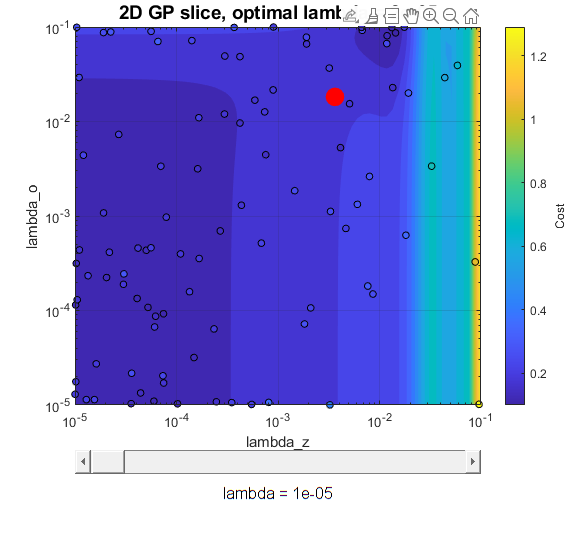

plotGP(gp, results)

## Sensitivity analysis

Global (trained kernel length scales)

lengthScales = gpGlobalSensitivity(gp)

lengthScales =     0.7535    4.8223   11.5713


Local (model gradient)

x_eval = table2array(X(1, :));
[gradMu, gradSigma2] = gpLocalSensitivity(gp, x_eval)

gradMu =     7.4190   -0.0769    0.0451


gradSigma2 = 1.0e-03 *

    0.8248    0.4691   -0.0260
